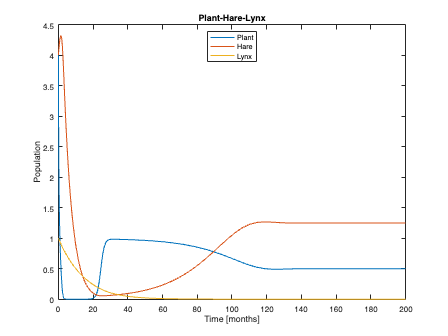

% Scenario 2: The lynx population goes extinct (population very close to zero) after a year, plants and 
% hares stabilize within 120 months.


t0 = 0; % start time of simulation [in months]
tfinal = 200; % end time of simulation [in months]
y0= [4 4 1]; % initial state i.e. number of plants, hares and lynxs at t=0
tspan = [t0 tfinal]; % time span defined by the start and end times of the simulation [in months]
a1 = 1; 
a2 = 0.2; 
b1 = 3;
b2 = 9;
d1 = 0.2; % keep same
d2 = 0.09; 

% reccomendations given in task description (here for reference - will
% delete later)
%y0  = [0.1-10  0.1-10  0.1-10] i.e. plant, hare, lynx
%a1 = [1-10]
%a2  = [0.1-1]
%b1 = [1-10]
%b2 = [1-10]
%d1 = [0.1-1]
%d2 = [0.01-1]

[t,y] = ode23(@(t,y) plants_hare_lynx_(t,y,a1,a2,b1,b2,d1,d2), tspan, y0);


% plotting the population over time
figure("Name",'hare-lynx for S2');
plot(t,y)
title('Plant-Hare-Lynx');
xlabel('Time [months]');
ylabel('Population');
legend('Plant','Hare','Lynx','Location','North');

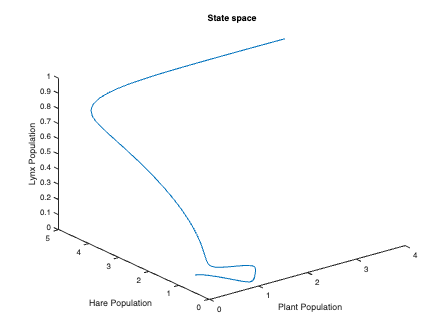

figure("Name",'State space for S2')
plot3(y(:,1),y(:,2),y(:,3))
title('State space')
xlabel('Plant Population')
ylabel('Hare Population')
zlabel('Lynx Population')